## **Jared Ham**

**Mech 513 - HW3**

**Airfoil CFD vs Thin Airfoil Theory vs Experimental Data**

ans = 2

ans = 5

ans = 2

 
S:\GitHub\MECH513-SimAndModeling>xfoil  0<XFOIL_RUN.txt 1>out.txt  


ans = 'PolarNACA0021.txt'

fid = 3

ans = 0

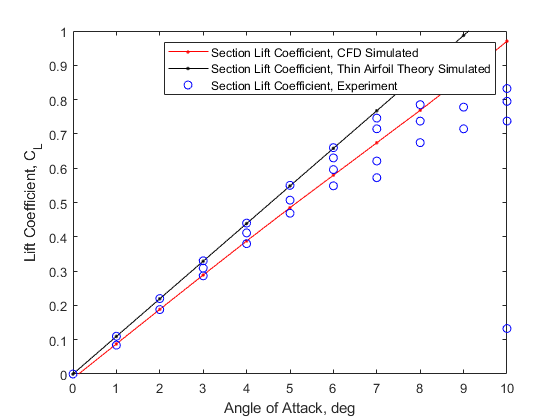

Data Collection is done, type ">> who" at the MATLAB prompt to see the outputs
CFD_AoA & CFD_CL are the angle of attack and lift coefficient as modeled using CFD
Exp_AoA & Exp_CL are the angle of attack and lift coefficient as measured by SNL using Experiment
TAS_AoA & TAS_CL are the angle of attack and lift coefficient as modeled using Thin Airfoil Assumption


MECH513_ValidationLab; %run to generate and load TAS, Xfoil and Experimental data into workspace

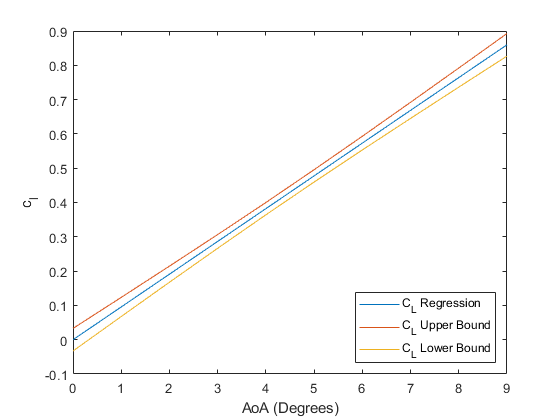

n = length(Exp_CL);
alpha = 0.1;
[Exp_linear_fit,Exp_linear_fit_gof] = fit(Exp_AoA, Exp_CL, 'poly1', 'Lower', [-Inf 0], 'Upper', [Inf 0]);
Slope = Exp_linear_fit.p1;
rsquare = Exp_linear_fit_gof.rsquare;
residuals_squared = ((Exp_AoA * Slope) - Exp_CL).^2;
s = sqrt(1/(n-1) * sum(residuals_squared));   % should be 0.0506

x_bar = mean(Exp_AoA);
s_x = std(Exp_AoA);
F_value = finv(1-alpha, 2, n-2);
SCI = s * sqrt(2*F_value*(1/n + (Exp_AoA - x_bar).^2 ./ ((n-1)*s_x^2)));

figure
plot(Exp_AoA(1:10), Exp_AoA(1:10) * Slope)
hold on;
plot(Exp_AoA(1:10), Exp_AoA(1:10) * Slope + SCI(1:10))
plot(Exp_AoA(1:10), Exp_AoA(1:10) * Slope - SCI(1:10))
ylabel({'c_l'});
xlabel({'AoA (Degrees)'});
legend1 = legend('show');
legend({'C_L Regression','C_L Upper Bound','C_L Lower Bound'},'location','southeast')
hold off;